# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file='rorc_model.xlsx';
data=CheckDataModel(file);

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [TCND30] are valid
INFO: cDataModel. Exergy values [TCND35] are valid
INFO: cDataModel. Exergy values [TCND50] are valid
INFO: cDataModel. Exergy values [TRB75] are valid
INFO: cDataModel. Exergy values [PBLR16] are valid
INFO: cDataModel. Exergy values [IHE60] are valid
INFO: cDataModel. Exergy values [noIHE] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [Internal] is valid
INFO: cDataModel. Resources Cost sample [External] is valid
INFO: cDataModel. Data Model rorc_model is valid


#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(2));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Cost Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod);

#### Show Results

res.summaryDiagnosis;

Fuel Impact:    -2.2700 (kW)
Malfunction Cost:     5.7766 (kW)


printResults(res);

Diagnosis Summary

 Key       MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)        ΔPt*
------------------------------------------------------------------------------
 BLR      -1.3130     -1.5520      0.0000     -1.3130      6.9952      0.0000
 TRB      -0.1418     -1.1000     -3.8200     -0.0931      0.2690     -8.0466
 IHE      -0.1482     -0.0710      0.0000     -0.1983     -0.0001      0.0000
 PMP      -0.0072     -0.0090      0.0000     -0.0122      0.1020      0.0000
 CND       0.0000      4.2820      0.0000      0.0145      0.0127      0.0000
 ENV      -1.6101      1.5500     -3.8200     -1.6021      7.3788     -8.0466


Malfunction Table (kW)

               BLR        TRB        IHE        PMP        CND        ΔPs
--------------------------------------------------------------------------
 BLR        0.0000    -0.3832    -0.1485     0.0000    -0.0361     0.0000
 TRB        0.0000     0.0000     0.0000    -0.0072     0.0000    -3.8200
 IHE        0.0000     0.2443    

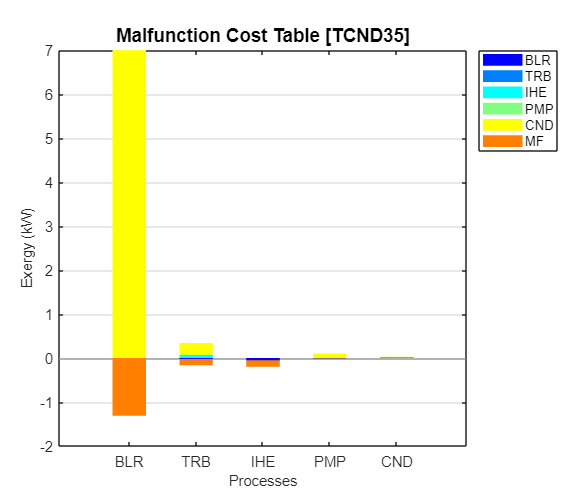

graphDiagnosis(res,'mfc',false);